## **Driver test program to check Clothoids library**

**Test G2 clothoid**

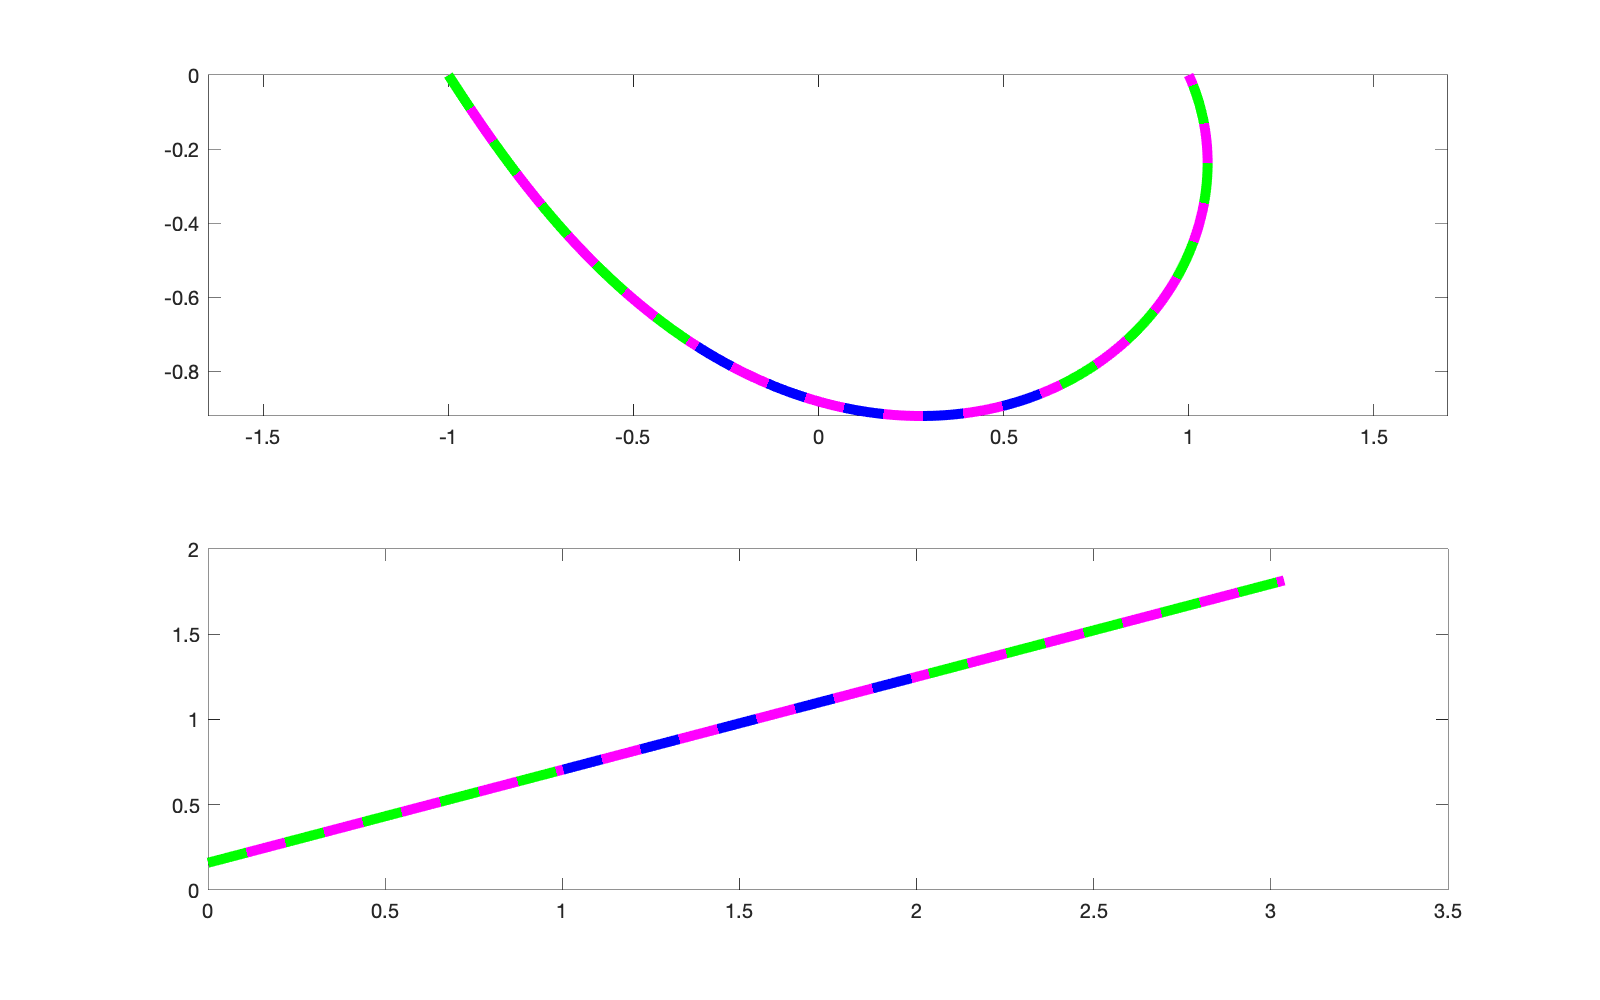

close all;

x0 = -1; y0 = 0; theta0 = -2+1;
x1 =  1; y1 = 0; theta1 = 2;

close all;
figure('Position',[1,1,800,500]);

C = ClothoidCurve();
S = ClothoidList();

iter = C.build_G1(x0,y0,theta0,x1,y1,theta1);

kappa0 = C.kappaBegin();
kappa1 = C.kappaEnd();

iter = S.build_3arcG2(x0,y0,theta0,kappa0,x1,y1,theta1,kappa1);

subplot(2,1,1);
C.plot(1000,'-m','Linewidth',5);
hold on;
S.plot(1000,{'--b','Linewidth',5},{'--g','Linewidth',5});
axis equal;

subplot(2,1,2);
C.plotCurvature(1000,'-m','Linewidth',5);
hold on
S.plotCurvature(1000,{'--b','Linewidth',5},{'--g','Linewidth',5});